%clear old vars
clear 
%connect to rasp
rpi = raspi()

rpi =   raspi with properties:

         DeviceAddress: '192.168.16.65'               
                  Port: 18734                         
             BoardName: 'Raspberry Pi 2 Model B'      
         AvailableLEDs: {'led0'}                      
  AvailableDigitalPins: [4,5,6,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27]
  AvailableSPIChannels: {'CE0','CE1'}                 
     AvailableI2CBuses: {'i2c-1'}                     
      AvailableWebcams: {'mmal service 16.1 (platform:bcm2835-v4l2)'}
           I2CBusSpeed: 100000                        
AvailableCANInterfaces: {}                            

  Supported peripherals


%use webcam funcito instead of using a USB camera
cam = cameraboard(rpi, "Resolution", '1280x720', 'ExposureMode', 'snow')

cam =   CameraBoard with properties:

                    Name: Camera Board   
              Resolution: '1280x720'      (View available resolutions)
                 Quality: 10              (1 to 100)
                Rotation: 0               (0, 90, 180 or 270)
          HorizontalFlip: 0              
            VerticalFlip: 0              
               FrameRate: 30              (2 to 90)
               Recording: 0              

   Picture settings
              Brightness: 50              (0 to 100)
                Contrast: 0               (-100 to 100)
              Saturation: 0               (-100 to 100)
               Sharpness: 0               (-100 to 100)

   Exposure and AWB
            ExposureMode: 'snow'          (

%take a phto using the camera
img = snapshot(cam)

img = 720×1280×3 uint8 array
img(:,:,1) =

    52    52    52    52    52    52    52    52    48    48    47    47    46    46    46    45    45    44    45    45    45    45    45    46    49    49    49    49    49    48    47    44    41    40    40    39    39    39    38    38    37    37    38    38    39    39    40    40    40    41    41    42    43    43    44    44    41    41    41    42    42    43    43    43    42    43    43    43    43    42    41    40    38    38    38    39    39    40    40    40    42    42    42    42    42    42    42    42    43    43    43    43    43    43    43    43    44    44    44    44    44    44    44    44    43    43    43    43    43    43    43    43    42    42    42    41    41    40    40    40    42    42    42    42    42    41    39    39    41    41    41    40    40    40    39    39    43    41    40    39    39    41    43    44    41    41    41    41    41    41    41    41    41    41    41    41    41    41    41   

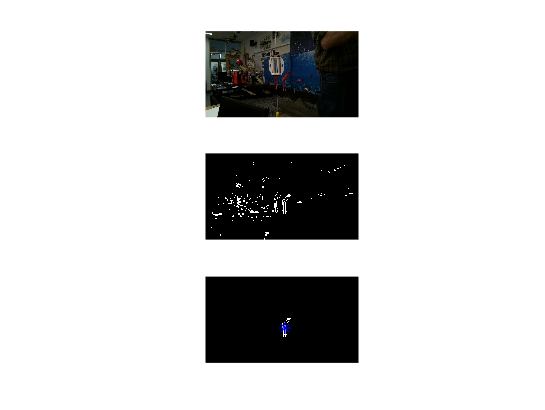

X-pixel value: 666.1351 
Y-pixel value: 425.0073 


whaleX = 666.1351

whaleY = 425.0073


% %If generating a function for calibrating, display image and run thresholder
% figure, imshow(img)
% colorThresholder(img)

% Choose whether to display frames for debugging
displayFrames = true;
[whaleX, whaleY] = findWhale(img, displayFrames)

function [targetX, targetY] = findWhale(frame, displayBool)
    % findWhale chooses the largest continuous segment of camera input that
    % contains the hue, saturation, value parameters that best captured only
    % the target whale (pink) against a blue background on 15 Feb 2022.
    % Inputs are image frame and optional boolean to display image for
    % debugging.
    % Tyler Ewald and CJ Hilty, 2022. Rev. A.
    
    
    
    % Extract the regions of the image that correspond to the whale
    % Based on the colors we selected for the mask generator
    [BW, maskedRGBImage] = createMask(frame); %calls auto-generated function
    
    % Create labels for the masked black-and-white image for every
    % continuous region
    % Values of L are 1:num based on what region the pixel is a part of or 0 otherwise
    [L, num] = bwlabel(BW,8); 
    
    if num > 0
        % Compute size of each continuous region, and find the largest region
        % Compares each of every 1280*720 entries (921600 pixels) in L
        % to the values 1:num, which turns that into a 921600*num matrix, then sums each column
        count_pixels_per_obj = sum(L(:)==(1:num)); 
        
        % Create new mask that only contains largest region
        [~,ind] = max(count_pixels_per_obj);
        biggest_blob = (L==ind);
        
        % Compute center of this region
        s = regionprops(biggest_blob, 'centroid');
        centroids = cat(1,s.Centroid);
        
        % Assign center of largest region to our output variables
        targetX = centroids(1);
        targetY = centroids(2);
        
        % Display the results
        if displayBool
            figure,
            % Display original image
            subplot(311), imshow(frame);
            % Display color-masked image
            subplot(312), imshow(BW);
            % Display largest blob with center marked
            subplot(313), imshow(biggest_blob); 
            hold on; plot(centroids(:,1),centroids(:,2),'b*'); hold off;
        
            fprintf(['X-pixel value: %.4f \n'], targetX)
            fprintf(['Y-pixel value: %.4f \n'], targetY)
    
        end
    else
        targetX = -1;
        targetY = -1;
        figure();
        imshow(frame);
    end
end